% 打开文件
fileID = fopen('data5\data5\train-01-images.svm', 'r');

% 读取文件内容
C = textscan(fileID, '%s', 'Delimiter', '\n');
fclose(fileID);

% 获取行数
numRows = length(C{1});

% 初始化存储数据的数组
apres = zeros(numRows, 4); % 假设有4列

% 将数据分割成不同列并存储到数组中
for i = 1:numRows
    % 将每行内容按空格分割
    line = strsplit(C{1}{i}, ' ');
    
    % 第一个元素为类别，将其存储到数组第一列
    apres(i, 1) = str2double(line{1});
    
    % 处理每个特征
    for j = 2:length(line)
        % 将特征索引和值分开555
        feature = strsplit(line{j}, ':');
        
        % 检查特征是否有两个部分（索引和值）
        if length(feature) == 2
            index = str2double(feature{1});
            value = str2double(feature{2});
            
            % 存储特征索引和值到对应列
            apres(i, index + 1) = value; % index + 1 因为第一列被用于存储类别
        else
            % 处理特征不完整的情况（如空值或格式错误）
            fprintf('特征格式错误或为空值\n');
        end
    end
end

特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值


% 显示结果
% disp(apres);

% 提取apres的第一列赋值给y
y = apres(:, 1);

% 删除apres的第一列
apres(:, 1) = [];


c = 0.01;
train_x = apres;
train_y = y;
% alpha 为我们求解器返回的结果
[m,n] = size(train_x);
f = ones(m,1);
f = -f;
Aeq = train_y';
beq = 0;
lb = zeros(m, 1);
ub = c * ones(m, 1);

% 计算H
H = zeros(m);
for i  = 1 : m
   for j = 1 : m
      H(i, j) = train_y(i) * train_y(j) *(train_x(i, 1) * train_x(j, 1) + train_x(i, 2) * train_x(j , 2));
   end
end

alpha = quadprog(H, f, [], [], Aeq, beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% train_x(1) 

% 计算w
w = zeros(1, 744);
for i = 1 : m
    t = alpha(i) * train_y(i) * train_x(i, :);
    w = w + t;
end

% 计算b
b = 0;
for s = 1 : m
    if mod(s, 100) == 0
        disp(s);
    end
    for i = 1 : m
        t = alpha(i) * train_y(i) * dot(train_x(i,:), train_x(s,:));
    end
    t2 = 1/train_y(s) - t;
    b = b + t2;
end

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500

        2600

        2700

        2800

        2900

        3000

        3100

        3200

        3300

        3400

        3500

        3600

        3700

        3800

        3900

        4000

        4100

        4200

        4300

        4400

        4500

        4600

        4700

        4800

        4900

        5000

        5100

        5200

        5300

        5400

        5500

        5600

        5700

        5800

        5900

        6000

        6100

        6200

        6300

        6400

        6500

        6600

        6700

        6800

        6900

        7000

        7100

        7200

        7300

        7400

        7500

    

b = b / m;

% 对训练集进行测试
train_test_y = train_x * w' + b;
train_test_y2 = sign(train_test_y);
tt_train = [];
[m, n] = size(train_test_y2);
for i = 1 : m
    if train_test_y2(i) ~= train_y(i)
        tt_train(end+1) = i;
    end
end
tt_train

tt_train =            8          19          40          57         110         189         322         417         493         639         831         839         930         967         974        1029        1083        1162        1185        1231        1237        1450        1514        1562        1564        1615        1626        1638        1669        1678        1755        1851        1889        1894        1969        1994        2034        2084        2176        2188        2308        2334        2405        2420        2500        2574        2646        2665        2770        2824


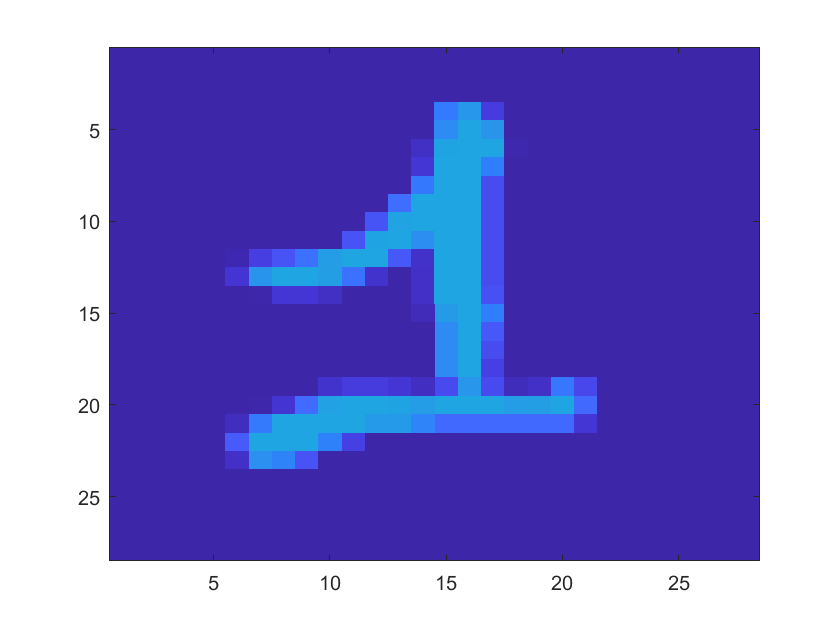

strimage('data5\data5\train-01-images.svm',8)

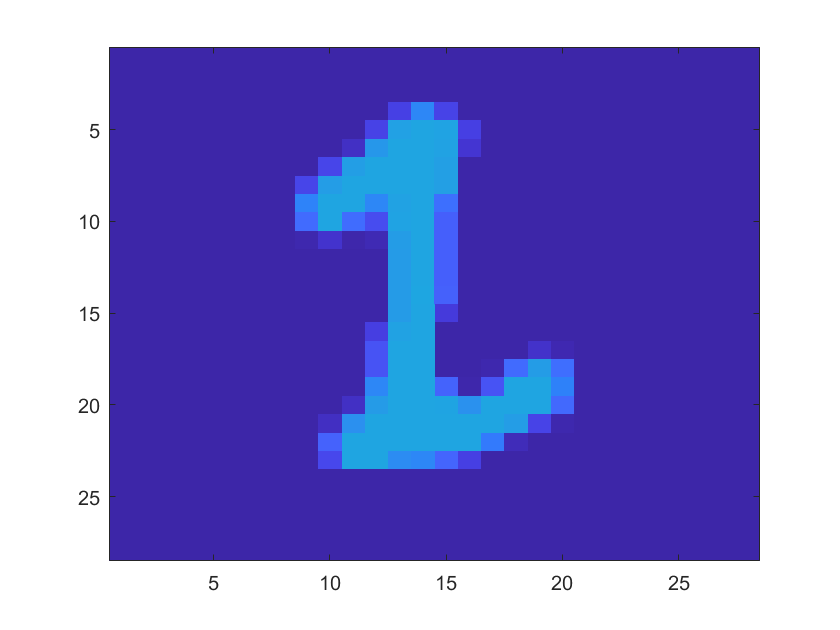

strimage('data5\data5\train-01-images.svm',19)

% 检测
% 打开文件
fileID = fopen('data5\data5\test-01-images.svm', 'r');

% 读取文件内容
C = textscan(fileID, '%s', 'Delimiter', '\n');
fclose(fileID);

% 获取行数
numRows = length(C{1});

% 初始化存储数据的数组
apres2 = zeros(numRows, 4); % 假设有4列

% 将数据分割成不同列并存储到数组中
for i = 1:numRows
    % 将每行内容按空格分割
    line = strsplit(C{1}{i}, ' ');
    
    % 第一个元素为类别，将其存储到数组第一列
    apres2(i, 1) = str2double(line{1});
    
    % 处理每个特征
    for j = 2:length(line)
        % 将特征索引和值分开
        feature = strsplit(line{j}, ':');
        
        % 检查特征是否有两个部分（索引和值）
        if length(feature) == 2
            index = str2double(feature{1});
            value = str2double(feature{2});
            
            % 存储特征索引和值到对应列
            apres2(i, index + 1) = value; % index + 1 因为第一列被用于存储类别
        else
            % 处理特征不完整的情况（如空值或格式错误）
            fprintf('特征格式错误或为空值\n');
        end
    end
end

特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值
特征格式错误或为空值


% 提取apres的第一列赋值给y
y = apres2(:, 1);

% 删除apres的第一列
apres2(:, 1) = [];
test_x = apres2;
test_y = y;


% 进行测试：
w_test = w(1:718);
result_y = test_x*(w_test') + b;

result_y2 = sign(result_y);

tt = [];
for i = 1 : 2115
    if result_y2(i) ~= test_y(i)
        tt(end+1) = i;
    end
end
tt

tt =           14          42         130         199         210         310         366         440         456         479         546         580         599         627         634         636         734         805         824         876         878        1106        1131        1173        1391        1398        1399        1521        1559        1644        1646        1664        1665        1683        1900        2106


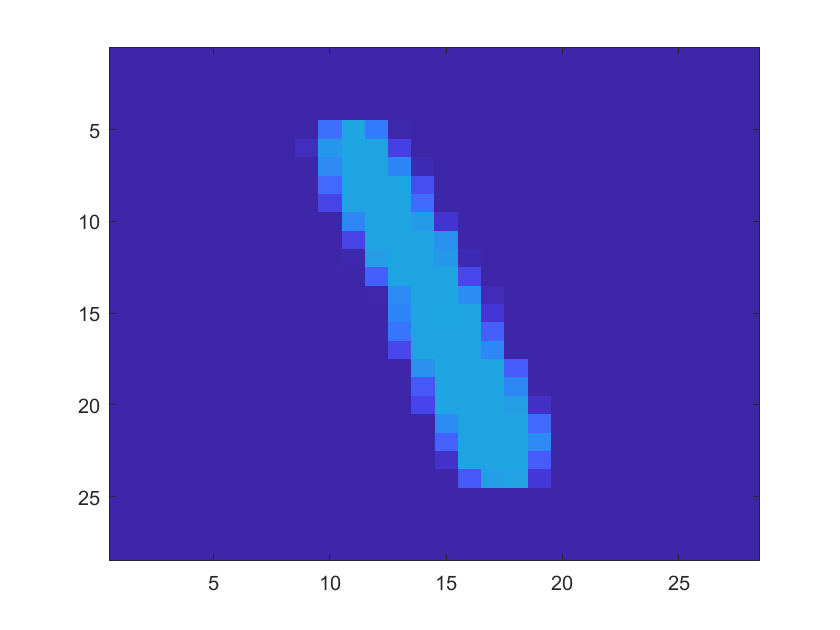

strimage('data5\data5\test-01-images.svm',14)

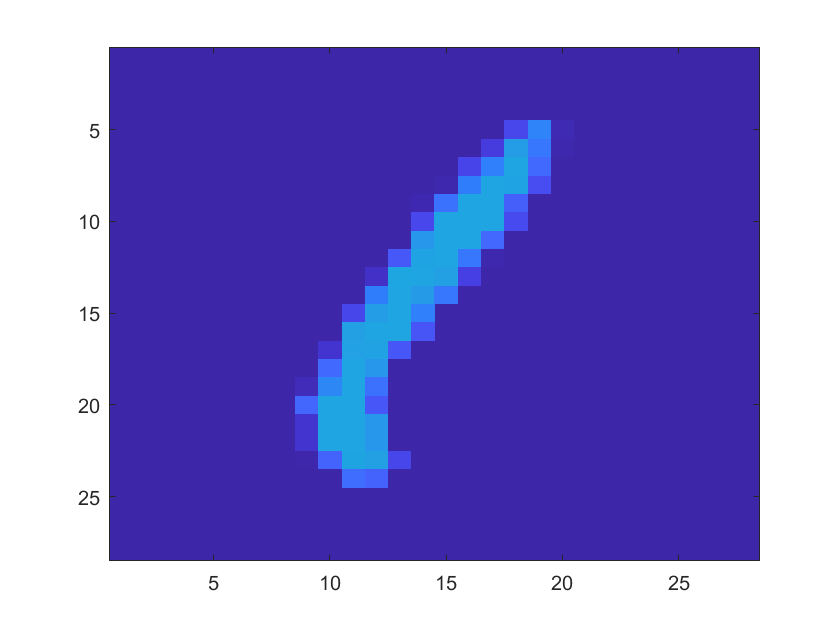

strimage('data5\data5\test-01-images.svm',24)